# Normalizing Electricity Usage Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

usage = table2array(readtable("../data/electricityData.xlsx", "Sheet", "usage", 'ReadVariableNames', false));
dates = table2array(readtable("../data/electricityData.xlsx", "Sheet", "dates", 'ReadVariableNames', false));
sectors = string(table2array(readtable("../data/electricityData.xlsx", "Sheet", "sectors", 'ReadVariableNames', false)));
total = usage(:, end);
whos

  Name           Size            Bytes  Class       Attributes

  dates        315x1              2542  datetime              
  sectors        1x4               360  string                
  total        315x1              2520  double                
  usage        315x4             10080  double                



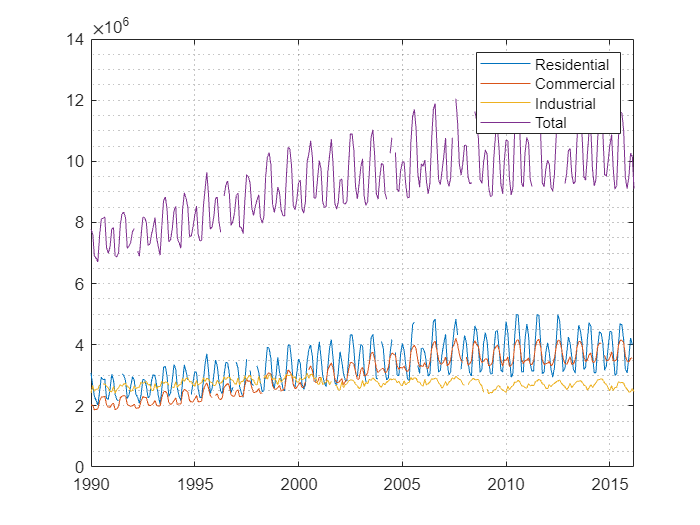

plot(dates, usage)  
grid minor
legend(sectors)

## Task 1

normTotal = normalize(total)

normTotal =    -1.2163
   -1.3382
   -1.9187
   -1.9753
   -2.0736
   -1.3805
   -0.9356
   -0.9219
   -0.8894
   -1.7028


## Task 2

normUsage = normalize(usage);

## Task 3

centeredUsage = normalize(usage, "center", "mean");

## Task 4

scaledUsage = normalize(usage, "scale", "first");

## Task 5

rangeUsage = normalize(usage, "range", [-1 1]);